 clc;
 clear all;

%generate the data bits 
N = 10000;
repeat = 0 ; %repeation flag 

% generate random  bits and map them to -1  and 1
%assuming tb and Eo = 1 

data = randi([0 1 ] ,N,1) *2 -1;
if(repeat > 0) 
    N= N*3;
    data = repelem(data,3);
    step = 3; %will be used in descion making
else
    step =1;
end

%channel creation
h =  (normrnd(0,sqrt(0.5),N,1)+j*normrnd(0,sqrt(0.5),N,1));

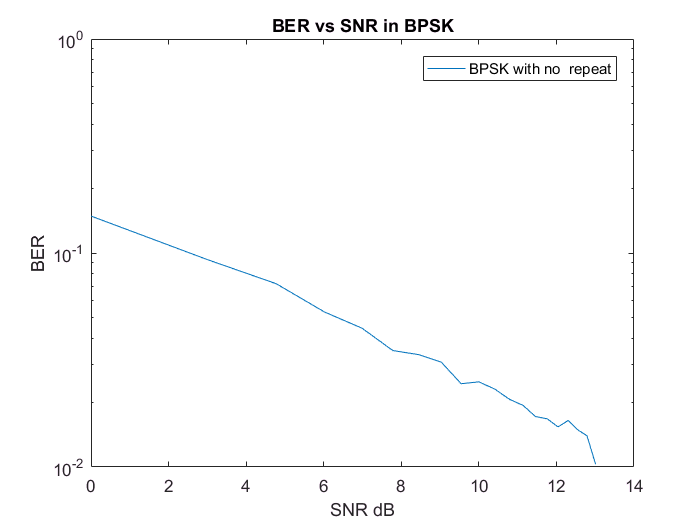

%generation of noise and getting the result  output at
%different No

BER= [];
for S = 1:1:20   %signal to noise ratio steps 
    No = 1/S ; 
    %noise generation n 
    n = (normrnd(0,sqrt(No/(2)),N,1)-j*normrnd(0,sqrt(No/(2)),N,1));
    %output formula  
    y = data.*h + n ;
    %there is no need for a correlator since
    %we work with base band signals 
    
    recieved_sig = y./h; %compensate for channel gain
    
    % descion making

    for i = 1:step:length(recieved_sig)
 %****** with repeat*******%       
        if(repeat >0)
            if(((recieved_sig(i)>0)&&(recieved_sig(i+1)>0))|| ((recieved_sig(i)>0)&&(recieved_sig(i+2)>0))||((recieved_sig(i+2)>0)&&(recieved_sig(i+1)>0)))
                               
            recieved_sig(i) = 1;
            recieved_sig(i+1) = 1;
            recieved_sig(i+2) = 1;
        else
            recieved_sig(i) = -1;
              recieved_sig(i+1) = -1;
            recieved_sig(i+2) = -1;
        end
        else
%***** no repeat descion****%            
        if(recieved_sig(i)>0)
            recieved_sig(i) = 1;
        else
            recieved_sig(i) = -1;
        end
end
    end
%check the BER using built in function symerr
[different,ratio] = symerr(recieved_sig,data);
BER = [BER ratio];
end
SNR = 1:1:20;
SNR_dB = 10*log10(SNR);
semilogy(SNR_dB,BER);
title('BER vs SNR in BPSK');
legend('BPSK with no  repeat');
xlabel('SNR dB');
ylabel('BER');

%********QPSK*******%
clc;
clear all;

%generate the data bits 
N = 50000;
repeat = 1 ; %repeation flag 
bits_symbol =2;

% generate random  bits and map them to -1  and 1
%assuming tb and Eo = 1 

data_bits = randi([0 1 ] ,N,1);

order =  [ 1 0 3 2  ];
data= qammod(data_bits,4,order,'InputType','bit'); %transform to QPSK


%************************mapping to constellation **********************&

        
if(repeat > 0) 
    N= N*3;
    data = repelem(data,3);
    step = 3; %will be used in descion making
else
    
    step =1;
end
N= N/bits_symbol;  

%channel creation
h = sqrt(0.5) *(normrnd(0,0.5,N,1)+j*normrnd(0,0.5,N,1));

%generation of noise and getting the result  output at
%different No

BER= [];
for S = 1:0.2:20   %signal to noise ratio steps 
    No = 1/S ; 
    %noise generation n 
    n = sqrt(No/(2))*(normrnd(0,0.5,N,1)-j*normrnd(0,sqrt(0.5),N,1));
    %output formula  
    y = data.*h + n ;
    %there is no need for a correlator since
    %we work with base band signals 
    
    recieved_sig = y./h; %compensate for channel gain
    
    % descion making

    for i = 1:step:length(recieved_sig)
 %****** with repeat*******%       
        if(repeat >0)
            if(((recieved_sig(i)>0)&&(recieved_sig(i+1)>0))|| ((recieved_sig(i)>0)&&(recieved_sig(i+2)>0))||((recieved_sig(i+2)>0)&&(recieved_sig(i+1)>0)))
                               
            recieved_sig(i) = 1;
            recieved_sig(i+1) = 1;
            recieved_sig(i+2) = 1;
        else
            recieved_sig(i) = -1;
              recieved_sig(i+1) = -1;
            recieved_sig(i+2) = -1;
        end
        else
%***** no repeat descion****%            
        if(recieved_sig(i)>0)
            recieved_sig(i) = 1;
        else
            recieved_sig(i) = -1;
        end
end
    end
recieved_bits = qamdemod(recieved_sig,4,order,'OutputType','bit');
%check the BER using built in function symerr
[different,ratio] = symerr(recieved_bits,data_bits);
BER = [BER ratio];
end

Undefined function or variable 'N'.


SNR = 1:0.2:20;
SNR_db = 10*log10(SNR);

plot(SNR,BER);
title('BER vs SNR in QPSK');
xlabel('SNR');
ylabel('BER');
